x = 1:6;
y = [16 18 21 17 15 12];
disp([x; y])

     1     2     3     4     5     6
    16    18    21    17    15    12



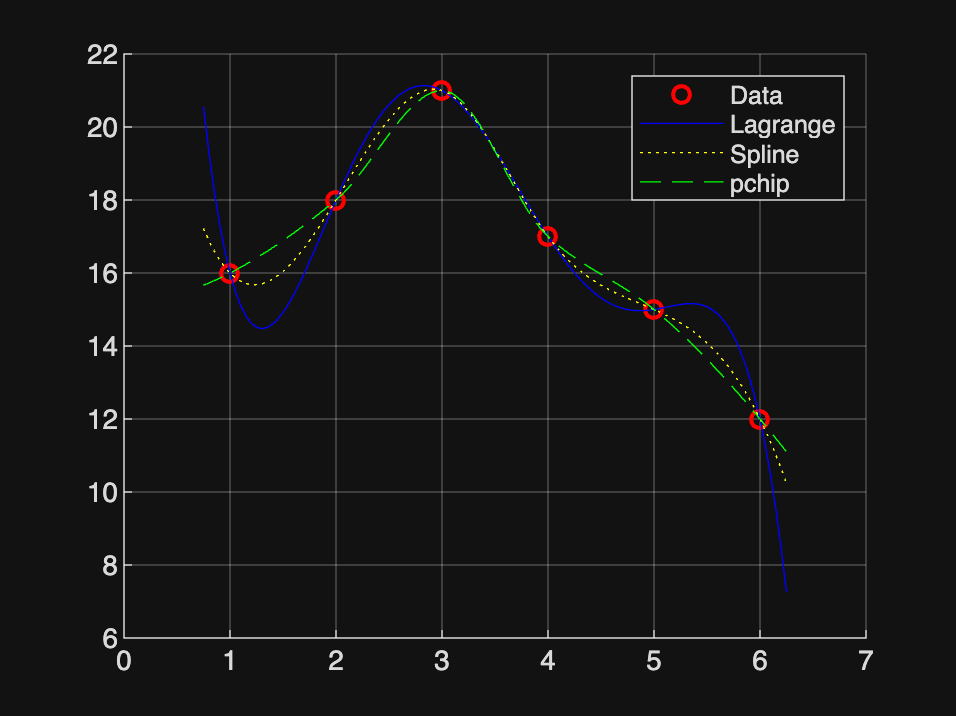

u = .75:.05:6.25;
v1=lagrange_polyinterp1(x,y,u);
v2=spline(x,y,u);
v3=pchip(x,y,u);
hold on
plot(x, y, 'ro', LineWidth=1.5);
plot(u, v1, 'b-')
plot(u, v2, 'y:')
plot(u, v3, 'g--')
hold off
legend('Data','Lagrange','Spline','pchip');
grid on;


sym_x=sym('x');
p= lagrange_polyinterp1(x,y,sym_x);
simplify(p)

$$ans = -\frac{29\,x^{5}}{120}+\frac{13\,x^{4}}{3}-\frac{695\,x^{3}}{24}+\frac{263\,x^{2}}{3}-\frac{579\,x}{5}+69$$

function v = lagrange_polyinterp1(x,f,u)
    n=length(x);
    m=length(u);
    v=zeros(m,1);
    
    for k=1:m
        sum_val=0;
        for j=1:n
            prod=1;
            for i=1:n
                if i~=j
                    prod=prod* (u(k)-x(i)) / (x(j)-x(i));
                end
            end
            sum_val=sum_val+prod*f(j);
        end
        if isa(u, 'sym')
            v=sum_val;
        else
            v(k)=sum_val;
        end
    end 
end